# ME 140 - Ch 12 Iterative Methods - In Class 10.14

## Problem 12.2

Use the Gauss-Seidel method to solve the following system until the percent relative error falls below 5%.

Use overrelaxation with lamda = 1.2 for part b

help GaussSeidel.m

  GaussSeidel: Gauss Seidel method
  [x,ea,iter] = GaussSeidel(A,b,es,maxit): Gauss Seidel without relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



A = [0.8 -0.4 0; -0.4 0.8 -0.4; 0 -0.4 0.8];
b = [41; 25; 105];

es = 5;
[x5,ea5,iter5] = GaussSeidel(A,b,es)

x5 =   167.8711
  239.1211
  250.8105


ea5 = 3.5020

iter5 = 6

            % 6 iterations required w/o relaxation
[x,ea,iter] = GaussSeidel(A,b)

x =   173.7500
  245.0000
  253.7500


ea = 6.4536e-06

iter = 25


x1 = A\b % simpler

x1 =   173.7500
  245.0000
  253.7500



% With overrelaxation
help GaussSeidelRelax

  GaussSeidel: Gauss Seidel method with relaxation
  [x,ea,iter] = GaussSeidelRelax(A,b,lambda,es,maxit): Gauss Seidel with relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  lambda = relation factor (default = 1)
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



lambda = 1.2;
[x5,ea5,iter5] = GaussSeidelRelax(A,b,lambda,es) 

x5 =   171.4230
  244.3887
  253.6222


ea5 = 4.9971

iter5 = 4

            % 4 iterations required w/ relaxation
[x,ea,iter] = GaussSeidelRelax(A,b,lambda)

x =   173.7500
  245.0000
  253.7500


ea = 6.1014e-06

iter = 12

## Problem 12.16

Determine the roots of the simultaneous nonlinear equations

(x-4)^2+(y-4)^2=5            x^2+y^2=16

Use a graphical approach to obtain your initial guesses. Determine the refined estimates with a) two equation Newton-Raphson b) fsolve

u = @(x) (x(1)-4)^2+(x(2)-4)^2-5;
v = @(x) x(1)^2+x(2)^2-16;
help meshgrid

 meshgrid   Cartesian rectangular grid in 2-D or 3-D
    [X,Y] = meshgrid(x,y) returns 2-D grid coordinates based on the
    coordinates contained in vectors x and y. X is a matrix where each row
    is a copy of x, and Y is a matrix where each column is a copy of y. The
    grid represented by the coordinates X and Y has length(y) rows and
    length(x) columns.
 
    [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the
    vectors x, y, and z. The grid represented by X, Y, and Z has size
    length(y)-by-length(x)-by-length(z).
 
    [X,Y] = meshgrid(x) is the same as [X,Y] = meshgrid(x,x), returning
    square grid coordinates with grid size length(x)-by-length(x).
 
    [X,Y,Z] = meshgrid(x) is the same as [X,Y,Z] = meshgrid(x,x,x),
    returning 3-D grid coordinates with grid size
    length(x)-by-length(x)-by-length(x).
 
    meshgrid

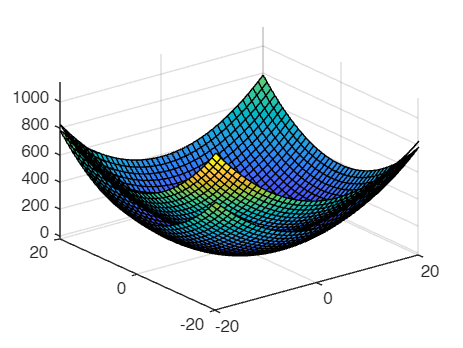

% Create a grid for plotting
[x1, x2] = meshgrid(-20:1:20, -20:1:20);

% Evaluate g(x1, x2) over the grid
G = (x1-4).^2+(x2-4).^2-5;
H = x1.^2+x2.^2-16;

% Plot 3D surface
figure;
surf(x1, x2, G);
hold on;
surf(x1, x2, H);


% Need to use jfreact2 and newtmult
x0 = [2;4];
% Need optimization toolbox setup
help newtmult

  newtmult: Newton-Raphson root zeroes nonlinear systems
  [x,f,ea,iter]=newtmult(func,x0,es,maxit,p1,p2,...):
  uses the Newton-Raphson method to find the roots of
  a system of nonlinear equations
  input:
  func = name of function that returns f and J
  x0 = initial guess
  es = desired percent relative error (default = 0.0001%)
  maxit = maximum allowable iterations (default = 50)
  p1,p2,... = additional parameters used by function
  output:
  x = vector of roots
  f = vector of functions evaluated at roots
  ea = approximate percent relative error (%)
  iter = number of iterations



help jfreact2

 jfreact2   Compute the Jacobian and function vector for multivariable Newton-Raphson.
 
    [J, f] = jfreact2(x, u, v)
 
    Numerically estimates the Jacobian matrix J and evaluates the function vector f
    for a system of two nonlinear equations f1(x1,x2) = 0 and f2(x1,x2) = 0.
 
    INPUTS:
        x  - 2×1 vector [x1; x2], current variable estimates.
        u  - Function handle for the first equation, f1(x1,x2).
        v  - Function handle for the second equation, f2(x1,x2).
        varargin - (optional) extra parameters to pass to u and v.
 
    OUTPUTS:
        J  - 2×2 Jacobian matrix of partial derivatives.
        f  - 2×1 vector of function values [f1; f2].
 
    The Jacobian is computed using finite differences:
        J(i,j) ≈ [f_i(x + Δx_j) - f_i(x)] / Δx_j
 
    Example:
        u = @(x,y) (x-4).^2 + (y-4).^2 - 5;
        v = @(x,y) (x-6).^2 + (y-2).^2 - 5;
        x0 = [3; 3];
        [J, f] = jfreact2(x0, u, v);
 


[J, f_jf] = jfreact2(x, u, v);
func = @jfreact2,x0 % not sure.
[x,f,ea,iter]=newtmult(func,x0) % not sure

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.

Error in newtmult (line 23)
[J,f]=func(x,varargin{:});

## Fsolve

xguess = [2:4];
f_1216 = @(x) [(x(1)-4)^2+(x(2)-4)^2-5; x(1)^2+x(2)^2-16;]
[x, xf] = fsolve(f_1216, xguess)
% Double check error messages we got